# Gravity Wave Hodograph

The current workflow to use this code is.

- run the setup section making sure you have selected the correct directory and sonde

- detect the altitude range of interest with the sliders the plot will update automatically 

- save the data if the selected data is desirable

- move on to the next file

- repeat steps 2-4 until the end of the data set.

- Plot all the data

## Set up

  % only click this when you first run the script. 
clearvars
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% select the data directory and what kind of sonde you are using
d = 'E:\GIT\App temp\eclipseData';
sonde = 1;
% if using DFM-17 set sonde = 1
% if using RS92 set sonde = 2
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

i = 1

i = 1

if sonde == 2
t = fullfile(d, "*.csv");
files = dir(t);
else
t = fullfile(d, "*.txt");
files = dir(t);
end
[temp, data, Alt, u, v, bvFreqSquared] = read_data(d, i, files, sonde);

Check for missing argument or incorrect argument data type in call to function 'preprocessDataNoResample'.

Error in hodographrunFile2>read_data (line 276)
    preprocessDataNoResample(data.Alt, u, v, data.T, data.P, RS);

% w = warning('query','last');
% id = w.identifier;
% warning('off',id);
figure(5)
clf;
plot3(u,data.Alt,v,'r');
grid on;
zlabel('v'); ylabel('Alt'); xlabel('u');
title('full data range')

## Data Range Selection

figure(1)
clf
i

i = 1

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Select the upper and lower altitude to visualize  
wl = 11840; % min
lower = find(data.Alt>=wl,1,'first');
wu = 21220; % max
upper = find(data.Alt>=wu,1,'first');
disp(files(i).name)

08202017C1_Center_Blaunch_Acer_174508.txt


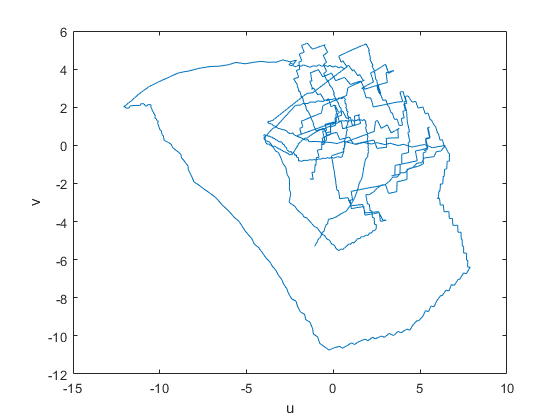

plot(u(lower:upper),v(lower:upper))
ylabel('v'); xlabel('u');

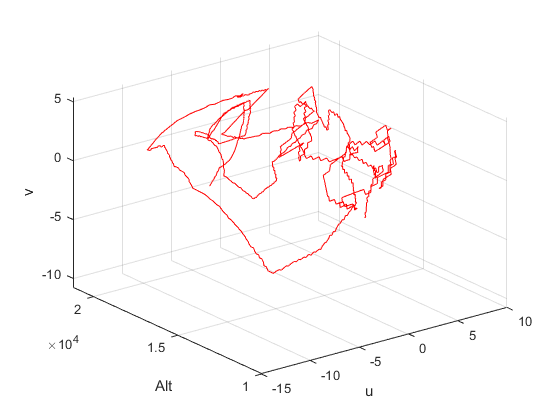

figure(2)
clf;
plot3(u(lower:upper),data.Alt(lower:upper),v(lower:upper),'r');
grid on;
zlabel('v'); ylabel('Alt'); xlabel('u');

## Save Data


  % click here to save the data

fprintf("%d, %d\n", Alt(lower), Alt(upper));

11840, 21222


T = table(Alt(lower:upper), u(lower:upper), v(lower:upper), temp(lower:upper), bvFreqSquared(lower:upper));
T.Properties.VariableNames = {'Alt' 'u' 'v' 'temp' 'bv2'};
[~, n, ~] = fileparts(files(i).name);
fname = sprintf(".\\hodograph\\%03u_%s-%d-%d.txt",i, n, Alt(lower), Alt(upper));
writetable(T, fname);


## Move on to next data file

 
i = i+1

i = 2

if i > size(files)
    warning("END of flight data");
end
[temp, data, Alt, u, v, bvFreqSquared] = read_data(d, i, files, sonde);

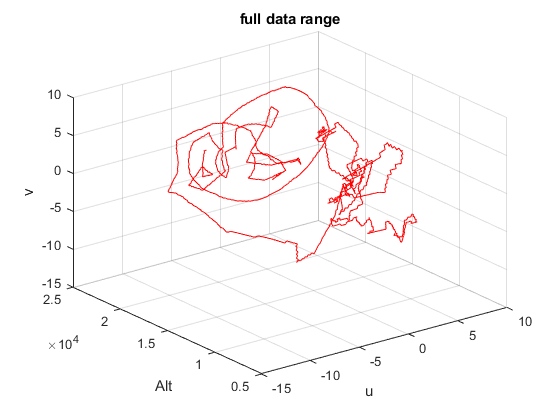

figure(5)
clf;
plot3(u(1:upper),data.Alt(1:upper),v(1:upper),'r');
grid on;
zlabel('v'); ylabel('Alt'); xlabel('u');
title('full data range')

## Plot All Data

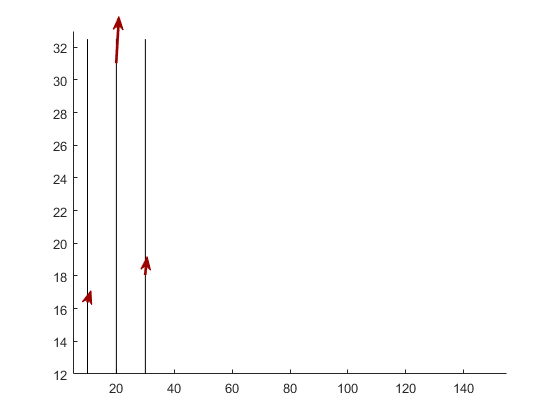

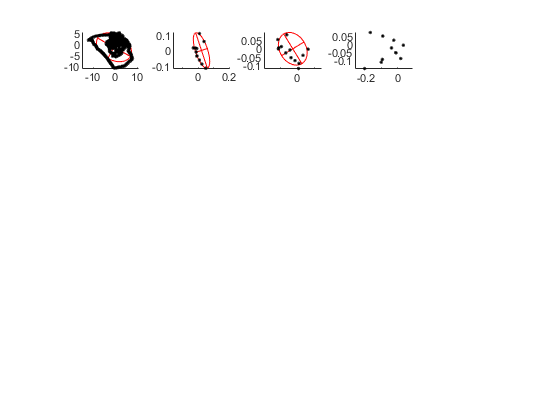

m:0.000335, lz:18764.000000, h:91.362700,, bv:0.000501


f: 001, ^{w}/{f}=1.5, t=60.7, m_z=18.8


m:0.032057, lz:196.000000, h:NaN,, bv:NaN


f: 002, ^{w}/{f}=3.0, t=18.1, m_z=0.2


m:0.031105, lz:202.000000, h:NaN,, bv:NaN


f: 003, ^{w}/{f}=1.3, t=31.3, m_z=0.2


Incorrect dimensions for matrix multiplication. Check that the number of columns in the first matrix matches the number of rows in the second matrix. To perform elementwise multiplication, use '.*'.


 
d = '.\hodograph';

t = fullfile(d, "*.txt");
files = dir(t); 
axs = [];
series_figure = figure;
hodo_fig = figure; offset = 10;
arrow_offset = 1 / 15;
counter = 1;
already_seen = [];
flight_num = [];
offsets = [];
coriolisFreq = coriolisFrequency(30.25);
unique_flights = strings(1,length(files));
for i = 1:length(files)
    a = sprintf('%02u',i);
    h = append('F',a);
    unique_flights(i) = h;
end
for k=1:size(unique_flights, 2)
    for i=1:size(files)
        flight_number = files(i).name(1:3);
        flight_number(1) = 'F';
    if strcmp(flight_number, unique_flights(k)) == 0
        %fprintf("%s %s\n", unique_flights(k), flight_number);
        continue;
    end
    % if str2num(flight_number(2:end)) ~= 23
    %     continue;
    % end
    data = readtable(fullfile(d, files(i).name));
    set(0, 'CurrentFigure', hodo_fig);
    ax = subplot(6, 5, i);
    axis equal; % this is needed to keep plots circular
    axs = [axs;ax];
    eps = fit_ellipse(data.u, data.v, ax);
    hold on
    plot(data.u, data.v, 'k.')
    lambda_z = 2*(data.Alt(end) - data.Alt(1));
    m = 2*pi / lambda_z;
    p = eps.phi;
    rot = [cos(p) -sin(p); sin(p) cos(p)];
    uv = [data.u data.v];
    uvrot = rot*uv';
    urot = uvrot(1, :);
    dT = data.temp(2:end) - data.temp(1:end-1);
    dz = data.Alt(2:end) - data.Alt(1:end-1);
    wf = eps.long_axis / eps.short_axis;
    bvMean = mean(data.bv2);
    intrinsicFreq = coriolisFreq*wf;
    %fprintf("%0.10f, %0.10f ", (coriolisFreq^2 * m^2)/abs(bvMean), wf^2 - 1);
    k_h = sqrt((coriolisFreq^2*m^2)/(abs(bvMean))*(wf^2 - 1)); % horizontal wavenumber (1 / meters)
    %fprintf("%f %f\n", intrinsicFreq, wf);
    intrinsicHorizPhaseSpeed = intrinsicFreq / k_h; % m/s
    fprintf("m:%f, lz:%f, h:%f,, bv:%f\n", m, lambda_z, intrinsicHorizPhaseSpeed, bvMean);
    k_h_2 = sqrt((intrinsicFreq^2 - coriolisFreq^2 )* (m^2 / abs(bvMean)));
    int2 = intrinsicFreq/k_h_2;
    % fprintf("m:%f, lz:%f, h:%f, kh:%f\n", m, lambda_z, intrinsicHorizPhaseSpeed, int2);
    dTdz = dT./dz;
    eta = mean(dTdz.*urot(1:end-1));
    if eta < 0
        p = p - pi;
    end
    str = sprintf("f: %s, ^{w}/{f}=%0.1f, t=%0.1f, m_z=%0.1f", ...
        files(i).name(1:3), wf, azimuthFromUnitCircle(rad2deg(p)),...
        lambda_z/1000);
    %title(str);
    fprintf("%s\n", str);
    set(0, 'CurrentFigure', series_figure);
    xlim([5, 155]);
    ylim([12, 33]);
    Alt_of_detection_km = mean(data.Alt) / 1000;
    x1 = counter*offset;
    x2 = counter*offset + wf*cosd(rad2deg(p));
    y1 = Alt_of_detection_km;
    y2 = Alt_of_detection_km + wf*sind(rad2deg(p));
    hold on;
    p1 = [x1 y1];
    p2 = [x2 y2];
    dp = p2-p1;
    %quiver(p1(1),p1(2),dp(1),dp(2), 'AutoScale', 'on', 'color','#9a0200', 'linewidth', 2);
    [xf, yf] = ds2nfu([x1 x2], [y1 y2]);
    annotation(gcf, 'arrow', xf,yf, 'color', '#9a0200', 'LineWidth', 2) %plot arrow angle of propagation length corresponds to magnitude of intrinsic frequency
    if strcmp(flight_number, "F23")
        if Alt_of_detection_km > 20 && Alt_of_detection_km < 24
            xc = [xf(1) - 0.125, xf(2)-0.02];
            yc = [yf(1) + 0.1, yf(1)+0.05];
            annotation(gcf, 'textarrow', xc, yc, 'String', 'Eclipse Wave #2')
        elseif Alt_of_detection_km > 20
            xc = [xf(1) - 0.125, xf(2)- 0.02];
            yc = [yf(1) + 0.1, yf(1)+0.05];
            annotation(gcf, 'textarrow', xc, yc, 'String', 'Eclipse Wave #3')
        end
        fprintf("%f\n", Alt_of_detection_km);
    end
    %plot([x1 x2], [y1 y2], 'color', '#9a0200', 'linewidth', 3);
    placeholder = [counter*offset counter*offset];
    plot(placeholder, [12, 32.5], 'k'); % plot Altitude in km.
    end
    offsets = [offsets, counter*offset];
    counter = counter + 1;
end

% 10 -> 150

linkaxes(axs, 'xy');
set(0, 'CurrentFigure', hodo_fig);
sgtitle("All hodographs for the radiosonde campaign")
set(0, 'CurrentFigure', series_figure);
% %offsets = offsets(1:end-1);
flight_num = flight_num(1:end-1, :);
xticks(offsets);
xticklabels(unique_flights); 
set(gca,'XTickLabelRotation', 45, 'fontsize', 16)
ylabel("Altitude of detection (km)") 
xlabel("Flight number")
title("Propagation direction and detection Altitude of gravity waves (hodograph method)", 'fontsize', 16);

## Wind shear detection


%  
% clear hi hi_final hi_max hi_min
% i=1
% current = files(i).name;
% current = fullfile(d, current);
% if sonde == 2
%     data = readRS92Data(current);
% else
%     data = readRadioSondeData(current);
% end
% %  [~, idx] = max(data.Alt);
% % data = data(1:idx, :);
% % data = data(data.Alt > 12000, :);
% % if isempty(data)
% %     warning("No data above 12000m");
% % end
% p = 3;
% hi = data.Alt-data.Alt(1);
% lmxt = [75, 465, 615, 715, 815, 1135, 1235, 1345, 1575, 1625, 1785, 2155, 2195, 2705, 2765, 2805, 2935, 3155, 3245, 3382, 3385, 3415, 3565, 3595, 3745, 3965, 4125, 4215, 4315, 4375, 4455];
% % [lmxt,P] = islocalmax(data.Ws,'MinProminence',p);
% % lmx = find(lmxt==1);
% lmx = lmxt;
%  for i = 1:length(lmx)
%     lmxx = lmx(end);
%     if lmx(i) <= (lmxx-400)
%         lmx_final(i) = lmx(i);
%     end
%  end
% 
% Ws_upper = data.Ws(lmx_final+400);
% Ws_lower = data.Ws(lmx_final);
% Ws_math = Ws_upper-Ws_lower;
% k = 1;
% for i = 1:length(lmx_final)
%     j = lmx_final(i);
%     if abs(data.Ws(j)) >= 7.5
%         hi_final(k) = hi(j);
%         k=k+1;
%     end
% end
% hi_max = hi_final;
% 
% % lmxt = [315, 1025, 115, 1295, 1454, 1805, 2005, 2115, 2595, 2663, 2685, 2795, 3383, 3395, 3435, 3465, 3545, 3625, 3775, 3845, 3955, 4105, 4205, 4295, 4345, 4474];
% % lmxt =  islocalmin(data.Ws,'MinProminence',p);
% % lmx = find(lmxt==1);
% % lmx = lmxt;
% % for i = 1:length(lmx)
% %     lmxx = lmx(end);
% %     if lmx(i) <= (lmxx-400)
% %         lmx_final(i) = lmx(i);
% %     end
% % end
% % 
% % Ws_upper = data.Ws(lmx_final+400);
% % Ws_lower = data.Ws(lmx_final);
% % Ws_math = Ws_upper-Ws_lower;
% % k = 1;
% % for i = 1:length(lmx_final)
% %     j = lmx_final(i);
% %     if abs(data.Ws(j)) >= 7.5
% %         hi_final(k) = hi(j);
% %         k=k+1;
% %     end
% % end
% % hi_min = hi_final
% % hi_final = [hi_max;hi_min]

function [temp, data, Alt, u, v, bvFreqSquared] = read_data(d, i, files, sonde)
    current = files(i).name;
    current = fullfile(d, current);
    if sonde == 2
        data = readRS92Data(current);
    else
        data = readRadioSondeData(current);
    end
    [~, idx] = max(data.Alt);
    data = data(1:idx, :);
    data = data(data.Alt > 6000, :);
    if isempty(data)
        warning("No data above 12000m");
    end
    if sonde == 2
        RS = 5;
    else
        RS = 5;
    end
    u = -(data.Ws) .* sind(data.Wd); % from MetPy
    v = -(data.Ws) .* cosd(data.Wd); %    
    [Alt, u, v, temp, bvFreqSquared] = ... 
    preprocessDataNoResample(data.Alt, u, v, data.T, data.P, RS);
end

function [upper, lower] = plot_elipse(data, wl, wu, u, v)
lower = find(data.Alt>=wl,1,'first');
upper = find(data.Alt>=wu,1,'first');
plot(u(lower:upper),v(lower:upper))
end
